# Visualizing Simulation Data

Authors: Ana Siesto Pérez and Xavier Marti Llull

Team:  G11-A

Shared Link with the teacher: [https://drive.matlab.com/sharing/b9ade108-0470-417b-9d56-c747ce4fbb80](https://drive.matlab.com/sharing/b9ade108-0470-417b-9d56-c747ce4fbb80) 

## Run the simulation model

clear
close all
sim('sl_lanechange')

ans =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Robot parameters and visualizing robot (robot and front wheel at origen)

Robot = [0 1 0; -0.3 0 0.3; 0 0 0; 1 1 1]

Robot =          0    1.0000         0
   -0.3000         0    0.3000
         0         0         0
    1.0000    1.0000    1.0000


T_Robot_0 = transl(0,0,0)

T_Robot_0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Front_wheel = [-0.1 0.1; 0 0; 0 0; 1 1]

Front_wheel =    -0.1000    0.1000
         0         0
         0         0
    1.0000    1.0000


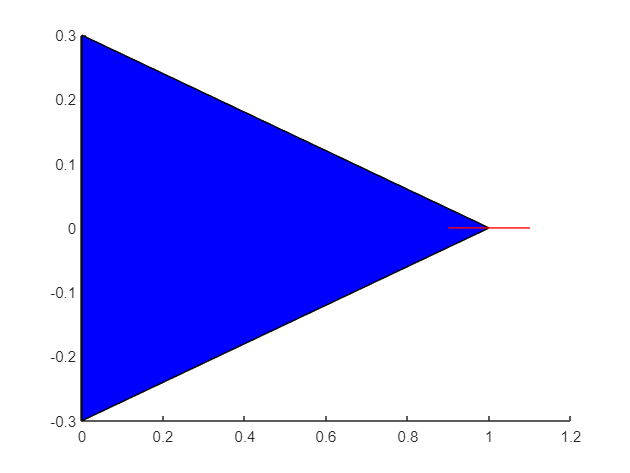

patch(Robot(1,:), Robot(2,:), [0 0 1])
line(Front_wheel(1,:)+1, Front_wheel(2,:), 'color', 'r')

## Workspace Data

x = ans.y(:,1)

x =          0
    0.0002
    0.0012
    0.0062
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200


y = ans.y(:,2)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


o = ans.y(:,3)

o =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


g = ans.y(:,4)

g =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Animation

close all
scatter(x,y,0.1)
axis([0 11 -0.5 1.5])
grid on
axis equal

hold on
hRobot = patch(Robot(1,:), Robot(2,:), 'b')

hRobot =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3]
     Vertices: [3×2 double]

  Show all properties


hFront_wheel = line(Front_wheel(1,:)+1, Front_wheel(2,:), 'color', 'r')

hFront_wheel =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.9000 1.1000]
              YData: [0 0]
              ZData: [1×0 double]

  Show all properties


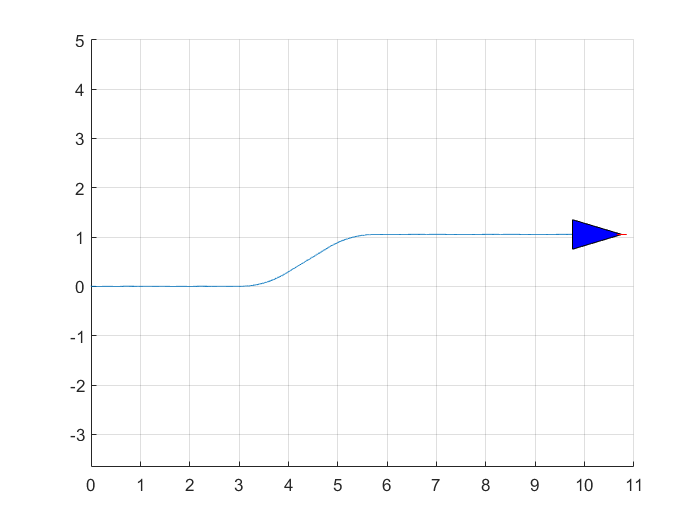


for i=1:504
    
    delete(hRobot);
    delete(hFront_wheel);
    T_Robot_0 = transl(x(i,1),y(i,1),0)*trotz(o(i,1));  
    Robot_Pose = transl(x(i,1),y(i,1), 0) * trotz(o(i,1)) * Robot;
    Front_wheel_Pose = T_Robot_0 * transl(1,0,0) * trotz(g(i,1)) * Front_wheel;
    hRobot = patch(Robot_Pose(1,:), Robot_Pose(2,:), 'b');
    hFront_wheel = line(Front_wheel_Pose(1,:), Front_wheel_Pose(2,:), 'color', 'r');
    pause(0.01);
end

## Visualizing wheels foot print

close all
scatter(x,y,0.1)
axis([0 11 -0.5 1.5])
grid on
axis equal

hold on
hRobot = patch(Robot(1,:), Robot(2,:), 'b')

hRobot =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3]
     Vertices: [3×2 double]

  Show all properties


hFront_wheel = line(Front_wheel(1,:)+1, Front_wheel(2,:), 'color', 'r')

hFront_wheel =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.9000 1.1000]
              YData: [0 0]
              ZData: [1×0 double]

  Show all properties


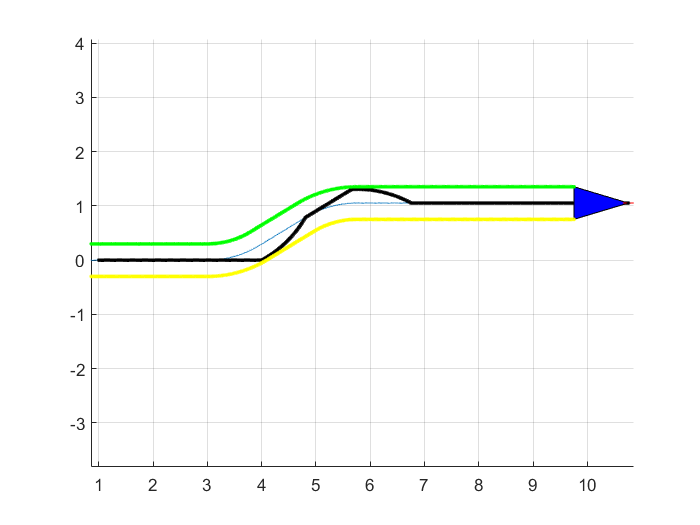

plot(Robot(1,1), Robot(2,1), '.', 'color', 'yellow')
plot(Robot(1,3), Robot(2,3), '.', 'color', 'green')
plot(Robot(1,2), Robot(2,2), '.', 'color', 'black')

for i=1:504
    
    delete(hRobot);
    delete(hFront_wheel);
    T_Robot_0 = transl(x(i,1),y(i,1),0)*trotz(o(i,1));
    Robot_Pose = transl(x(i,1),y(i,1), 0) * trotz(o(i,1)) * Robot;
    Front_wheel_Pose = T_Robot_0 * transl(1,0,0) * trotz(g(i,1)) * Front_wheel;
    hRobot = patch(Robot_Pose(1,:), Robot_Pose(2,:), 'b');
    hFront_wheel = line(Front_wheel_Pose(1,:), Front_wheel_Pose(2,:), 'color', 'r');
    plot(Robot_Pose(1,1), Robot_Pose(2,1), '.', 'color', 'yellow');
    plot(Robot_Pose(1,3), Robot_Pose(2,3), '.', 'color', 'green');
    plot(Robot_Pose(1,2), Robot_Pose(2,2), '.', 'color', 'black');
    pause(0.01);
end